## Introduction

This document demonstrates the use of the DoptFracPoly function to find D-optimal designs for fractional polynomials in logistic regression.

Start with a standard polynomial, $1 + x + x^2$. We must specify nominal coefficient values, the powers on x, the number of design points, and whether to calculate the sensitivity function.

% default algorithm settings
% Genetic algorithm with default parameters
algo = {@GA, 100000, 1000, 1, 20, 1, 20};

GA on 1-objective 6-variable UserProblem (  1.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.31s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.34s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.37s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.41s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.45s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.48s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.51s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.54s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.57s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.60s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.63s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.65s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.68s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

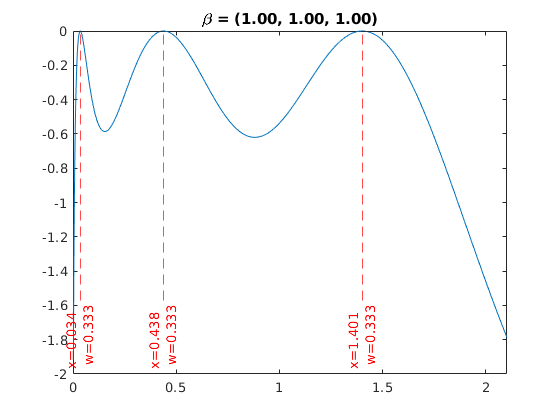

beta = [1,1,1];
powers = [1, 2];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

At the end of the console output, the optimal design is displayed along with the values of the sensitivity function at the design points. The function will also plot the sensitivity function for the design found.

Now suppose we want to find the optimal design for $1 + x^{-1} + \sqrt{x}$. All we need to do is to change the powers vector.

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.28s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.31s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.37s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.42s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

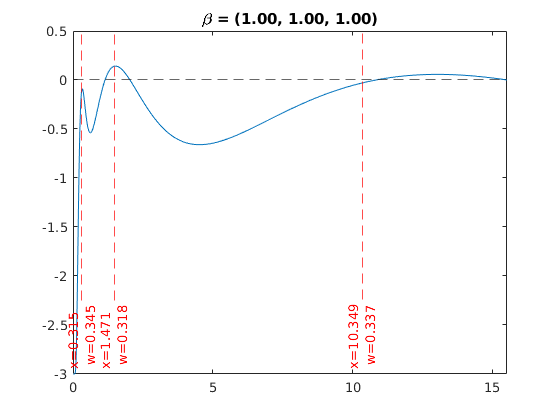

% right side shouldn't be positive
beta = [1,1,1];
powers = [-1, 0.5];
pts = 3;
sens = true;

obj = DoptFracPoly(beta, powers, pts, sens, algo);

## Examples of Designs

In their original paper, Royston and Altman give two applied examples of logistic regression using fractional polynomials. In both cases, they find the best values of the powers so that the model fits the data opitmally. The final regression coefficients are unknown. Therefore, we will find optimal designs for the two sets of powers and experiment with different values for the regression coefficients.

### In Vitro Fertilization example, p = (-1, 1)

powers = [-1, -1];

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.29s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.41s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.44s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.48s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

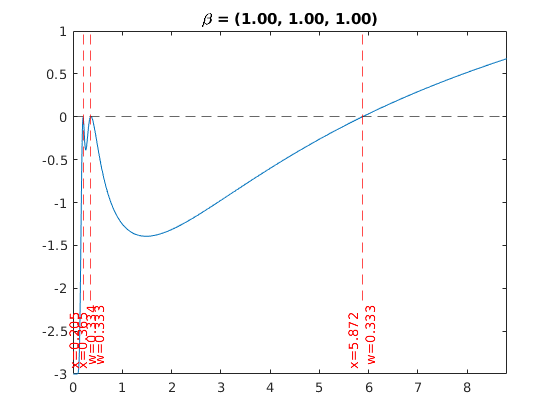

% simple case
% problem with positive values
beta = [1,1,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.18s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.28s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.31s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.37s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.40s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.43s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.46s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

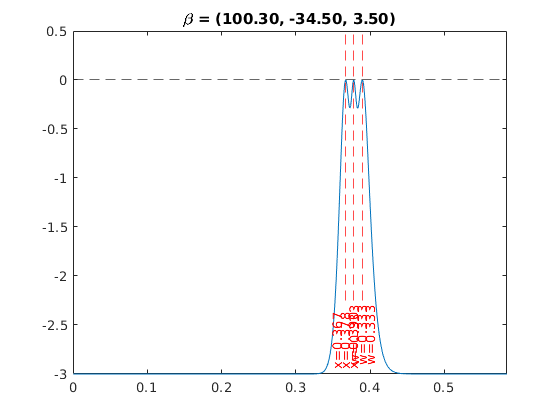

% more complicated case
% works perfectly
beta = [100.3,-34.5,3.5];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

There might be some difficulty with repeated powers that causes the problems on the right side of the plot.

### Myelomatosis example, p = (-2, 3)

The model used for this example from Royston and Altman included other covariates, but it is still interesting to look at the fractional polynomial in isolation.

powers = [-2, 3];

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.27s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.31s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.40s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.43s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.46s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.49s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

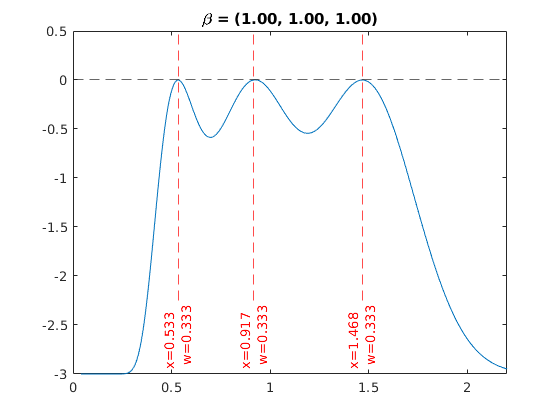

% simple case
beta = [1,1,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.13s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.30s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.42s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.45s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.48s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

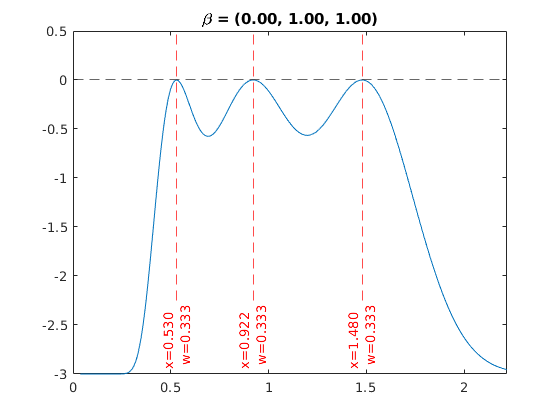

% beta0 = 0
beta = [0,1,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 8-variable UserProblem (  1.00%), 0.05s passed...
GA on 1-objective 8-variable UserProblem (  2.00%), 0.10s passed...
GA on 1-objective 8-variable UserProblem (  3.00%), 0.13s passed...
GA on 1-objective 8-variable UserProblem (  4.00%), 0.17s passed...
GA on 1-objective 8-variable UserProblem (  5.00%), 0.20s passed...
GA on 1-objective 8-variable UserProblem (  6.00%), 0.24s passed...
GA on 1-objective 8-variable UserProblem (  7.00%), 0.27s passed...
GA on 1-objective 8-variable UserProblem (  8.00%), 0.31s passed...
GA on 1-objective 8-variable UserProblem (  9.00%), 0.34s passed...
GA on 1-objective 8-variable UserProblem ( 10.00%), 0.37s passed...
GA on 1-objective 8-variable UserProblem ( 11.00%), 0.41s passed...
GA on 1-objective 8-variable UserProblem ( 12.00%), 0.44s passed...
GA on 1-objective 8-variable UserProblem ( 13.00%), 0.48s passed...
GA on 1-objective 8-variable UserProblem ( 14.00%), 0.51s passed...
GA on 1-objective 8-variable UserProblem ( 15.00

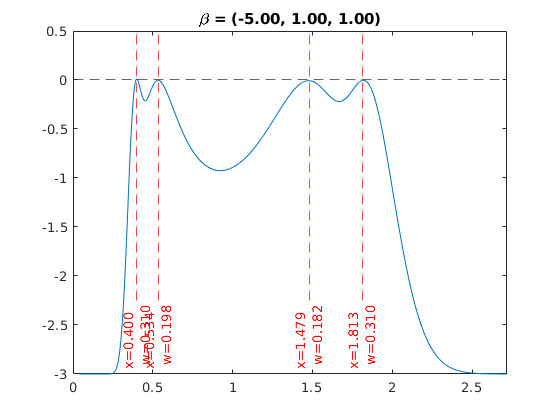

% beta0 < 0 
% this is now a 4 point design
beta = [-5,1,1];
pts = 4;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

% beta1 = 0
% matrix inverse trouble
% pinv may help
beta = [1,0,1];
pts = 2;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.06s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.18s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.27s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.30s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.42s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.45s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.48s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

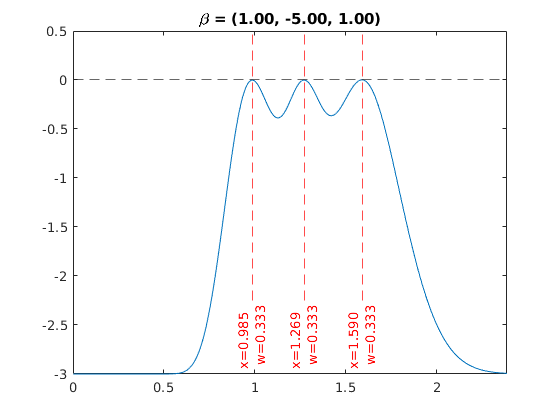

% beta1 < 0
beta = [1,-5,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.18s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.27s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.42s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.45s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

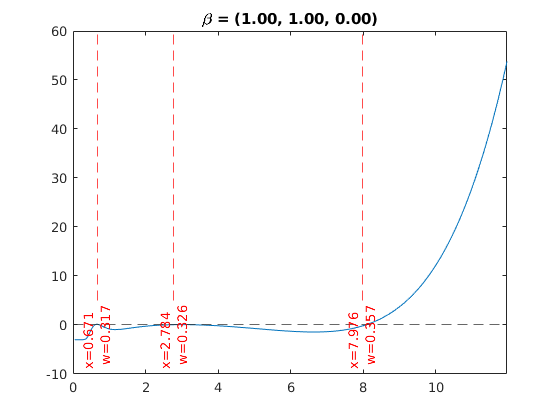

% beta2 = 0
beta = [1,1,0];
pts = 3;
sens = true;

obj = DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.18s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.28s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.31s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.34s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.37s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.40s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.43s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.46s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

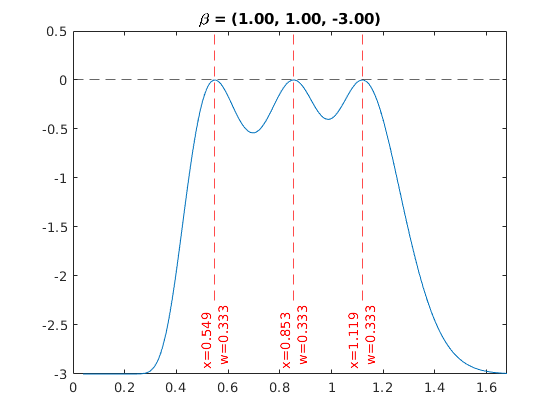

% beta2 <0
beta = [1,1,-3];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.10s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.13s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.28s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.41s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.44s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.47s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

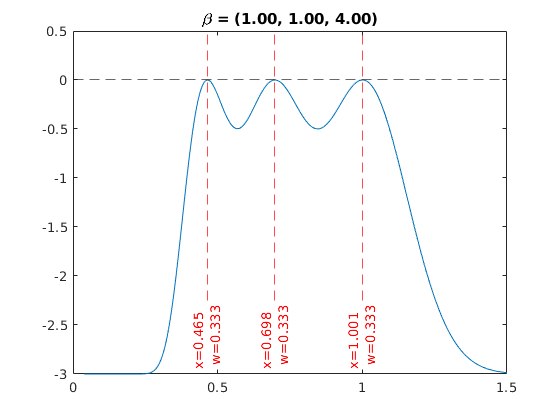

% beta2 > 1
beta = [1,1,4];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.07s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.29s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.41s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.44s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

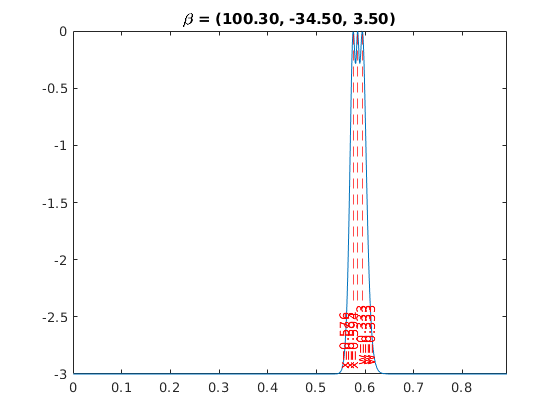

% same complicated case from last example
% also 3 sharp peaks
beta = [100.3,-34.5,3.5];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

Setting p = (-2, 3) seems to result in mostly equally weighted 3 point designs. Like for quadratic models, setting the intercept a negative value seems to produce a 4 point design. Again, similar to the quadratic case, the 3 point designs seem to be equally weighted and the 4 point designs seem to be symmetrically weighted. Setting beta1 = 0 causes some matrix inversion problems. It would probably be a good idea to set beta2 = 0 if we want to use a 1st degree fractional polynomial.

### Royston et  al. 1999, p = (-2,-2)

In "The use of fraction polynomials to model continuous risk variables in epidemiology", Royston et. al. model the relationship between probability of death and number of cigarettes per day. The fractional polynomial that best fit the data in this paper was p = (-2, 2). This is another case of a repeated power, which means finding the design probably will be more difficult.

powers = [-2, -2];

GA on 1-objective 6-variable UserProblem (  1.00%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.13s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.29s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.41s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.44s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.47s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

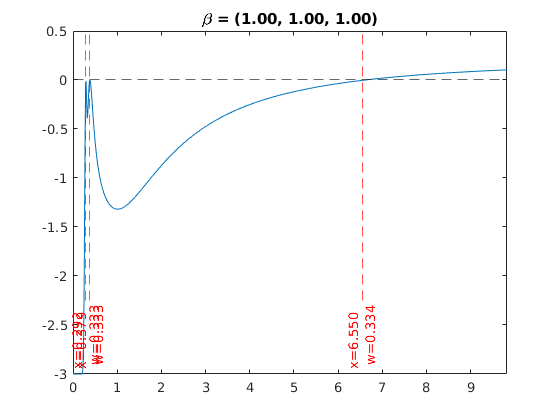

% simple case
% positive values
beta = [1,1,1];
pts = 3;
sens = true;

DoptFracPoly(beta, powers, pts, sens, algo);

## Testing different algorithm options

For the last example, the algorithm did not find the optimal design. We can see this because the value of the sensitivity function becomes greater than 0. This was the problem with some other examples too. Maybe we can find the optimal design using a different algorithm, so let's play around in a more organized fashion.

powers = [-2, -2];
beta = [1,1,1];
sens = true;

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.15s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.25s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.29s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.42s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.46s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.49s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

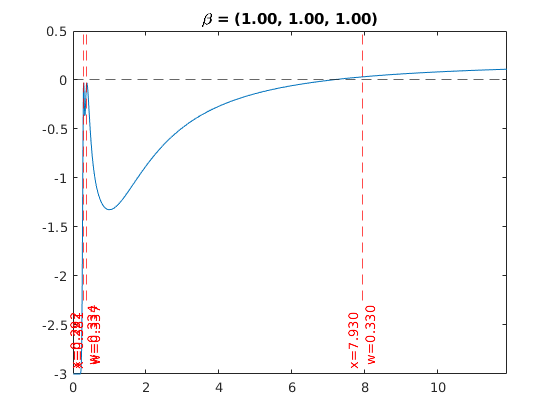

% GA
% can get slighly lower objective function by increasing exploration
% plot doesn't make sense
% obj = 2.577237
pts = 3;
algo = {@GA, 100000, 1000, 1, 20, 1, 20};
obj = DoptFracPoly(beta, powers, pts, sens, algo);

CSO on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
CSO on 1-objective 6-variable UserProblem (  1.50%), 0.07s passed...
CSO on 1-objective 6-variable UserProblem (  2.00%), 0.09s passed...
CSO on 1-objective 6-variable UserProblem (  2.50%), 0.10s passed...
CSO on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
CSO on 1-objective 6-variable UserProblem (  3.50%), 0.14s passed...
CSO on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
CSO on 1-objective 6-variable UserProblem (  4.50%), 0.18s passed...
CSO on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
CSO on 1-objective 6-variable UserProblem (  5.50%), 0.21s passed...
CSO on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
CSO on 1-objective 6-variable UserProblem (  6.50%), 0.24s passed...
CSO on 1-objective 6-variable UserProblem (  7.00%), 0.26s passed...
CSO on 1-objective 6-variable UserProblem (  7.50%), 0.27s passed...
CSO on 1-objective 6-variable User

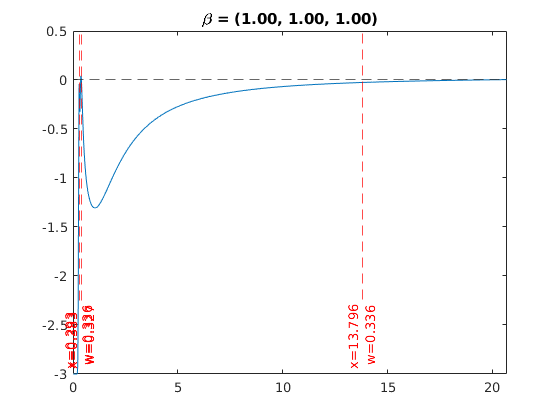

% CSO
% performance is about the same as others
pts = 3;
algo = {@CSO, 100000, 1000, 0.001}; % social factor
obj = DoptFracPoly(beta, powers, pts, sens, algo);

DE on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
DE on 1-objective 6-variable UserProblem (  2.00%), 0.09s passed...
DE on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
DE on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
DE on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
DE on 1-objective 6-variable UserProblem (  6.00%), 0.23s passed...
DE on 1-objective 6-variable UserProblem (  7.00%), 0.26s passed...
DE on 1-objective 6-variable UserProblem (  8.00%), 0.29s passed...
DE on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
DE on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
DE on 1-objective 6-variable UserProblem ( 11.00%), 0.38s passed...
DE on 1-objective 6-variable UserProblem ( 12.00%), 0.41s passed...
DE on 1-objective 6-variable UserProblem ( 13.00%), 0.44s passed...
DE on 1-objective 6-variable UserProblem ( 14.00%), 0.47s passed...
DE on 1-objective 6-variable UserProblem ( 15.00

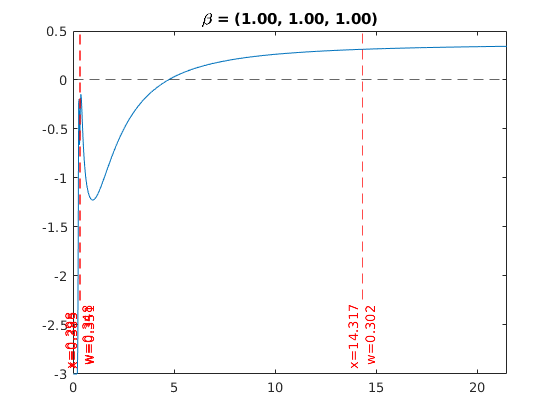

% DE
% performance isn't great
pts = 3;
algo = {@DE, 100000, 1000, 0.9, 0.5}; % crossover and mutation factor
obj = DoptFracPoly(beta, powers, pts, sens, algo);

OFA on 1-objective 6-variable UserProblem (  0.10%), 0.02s passed...
OFA on 1-objective 6-variable UserProblem (  0.20%), 0.03s passed...
OFA on 1-objective 6-variable UserProblem (  0.30%), 0.03s passed...
OFA on 1-objective 6-variable UserProblem (  0.40%), 0.04s passed...
OFA on 1-objective 6-variable UserProblem (  0.50%), 0.04s passed...
OFA on 1-objective 6-variable UserProblem (  0.60%), 0.05s passed...
OFA on 1-objective 6-variable UserProblem (  0.70%), 0.05s passed...
OFA on 1-objective 6-variable UserProblem (  0.80%), 0.05s passed...
OFA on 1-objective 6-variable UserProblem (  0.90%), 0.06s passed...
OFA on 1-objective 6-variable UserProblem (  1.00%), 0.06s passed...
OFA on 1-objective 6-variable UserProblem (  1.10%), 0.07s passed...
OFA on 1-objective 6-variable UserProblem (  1.20%), 0.07s passed...
OFA on 1-objective 6-variable UserProblem (  1.30%), 0.07s passed...
OFA on 1-objective 6-variable UserProblem (  1.40%), 0.07s passed...
OFA on 1-objective 6-variable User

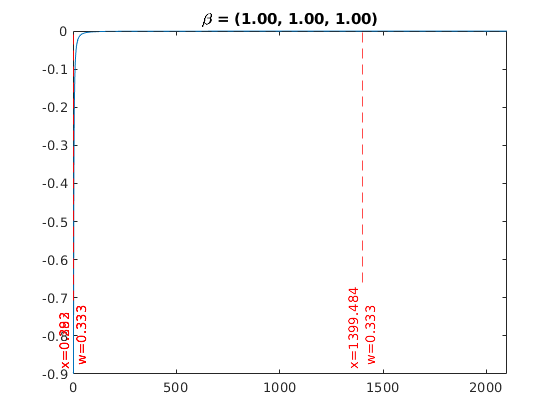

% Ooptimal foraging
% performance is about the same
% haven't tried tuning yet with this method
pts = 3;
algo = {@OFA, 100000, 100};
obj = DoptFracPoly(beta, powers, pts, sens, algo);

PSO on 1-objective 6-variable UserProblem (  1.00%), 0.05s passed...
PSO on 1-objective 6-variable UserProblem (  2.00%), 0.10s passed...
PSO on 1-objective 6-variable UserProblem (  3.00%), 0.13s passed...
PSO on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
PSO on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
PSO on 1-objective 6-variable UserProblem (  6.00%), 0.22s passed...
PSO on 1-objective 6-variable UserProblem (  7.00%), 0.25s passed...
PSO on 1-objective 6-variable UserProblem (  8.00%), 0.29s passed...
PSO on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
PSO on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
PSO on 1-objective 6-variable UserProblem ( 11.00%), 0.38s passed...
PSO on 1-objective 6-variable UserProblem ( 12.00%), 0.41s passed...
PSO on 1-objective 6-variable UserProblem ( 13.00%), 0.44s passed...
PSO on 1-objective 6-variable UserProblem ( 14.00%), 0.47s passed...
PSO on 1-objective 6-variable User

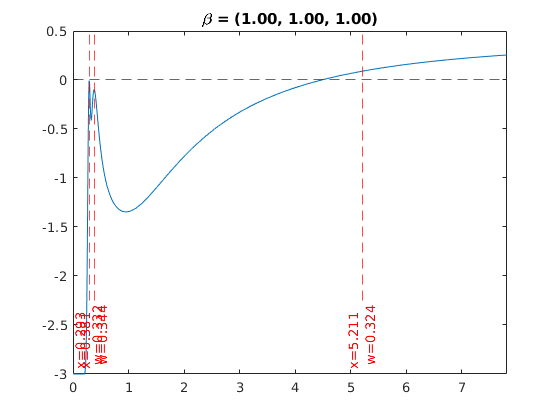

% PSO
% pretty sure I got the optimal before with PSO but can't replicate
pts = 3;
algo = {@PSO, 100000, 1000, 0.4};
obj = DoptFracPoly(beta, powers, pts, sens, algo);

% SHADE
% obj = 2.5772
% about the same performance and weird plot like CSO
% other times breaks and gives imaginary numbers
pts = 3;
algo = {@SHADE, 10000, 100};
obj = DoptFracPoly(beta, powers, pts, sens, algo);